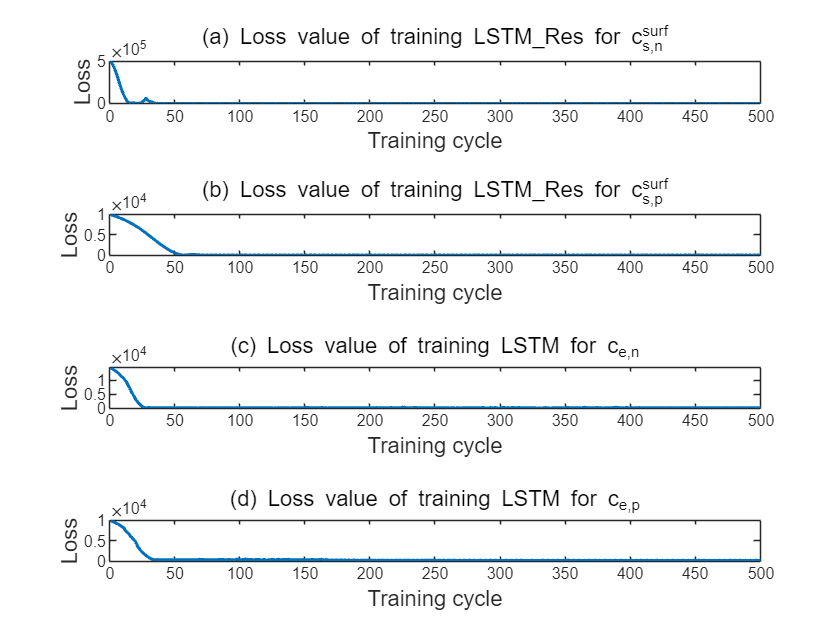

clc;
clear;
Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

I=-17.5*[ones(3590,1)];
Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;
t=1:length(I);

I05=-17.5*[ones(7200,1)]*0.5;
Jn05=I05*Rsn/3/epssn/F/A/Ln;
Jp05=-I05*Rsp/3/epssp/F/A/Lp;
t05=1:length(I05);

I2=-17.5*[ones(1660,1)]*2;
Jn2=I2*Rsn/3/epssn/F/A/Ln;
Jp2=-I2*Rsp/3/epssp/F/A/Lp;
t2=1:length(I2);

load trained_net\info_en_20230607.mat;
load trained_net\info_ep_20230607.mat;
load trained_net\info_sp_20231023.mat;
load trained_net\info_sn_20231023.mat;

figure(1);
clf;
tiled=tiledlayout(4,1);
nexttile
plot(info_sn.TrainingLoss,LineWidth=1.5);
title("(a) Loss value of training LSTM\_Res for c_{s,n}^{surf}","FontSize",11);
ylabel('Loss',"FontSize",11);
xlabel("Training cycle","FontSize",11);
nexttile
plot(info_sp.TrainingLoss,LineWidth=1.5);
title("(b) Loss value of training LSTM\_Res for c_{s,p}^{surf}","FontSize",11);
ax=gca;
ax.YAxis.Exponent=4;
ylabel('Loss',"FontSize",11);
xlabel("Training cycle","FontSize",11);
nexttile
plot(info_en.TrainingLoss,LineWidth=1.5);
title("(c) Loss value of training LSTM for c_{e,n}","FontSize",11);
ax=gca;
ax.YAxis.Exponent=4;
ylabel('Loss',"FontSize",11);
xlabel("Training cycle","FontSize",11);
nexttile
plot(info_ep.TrainingLoss,LineWidth=1.5);
title("(d) Loss value of training LSTM for c_{e,p}","FontSize",11);
ax=gca;
ax.YAxis.Exponent=4;
ylabel('Loss',"FontSize",11);
xlabel("Training cycle","FontSize",11);

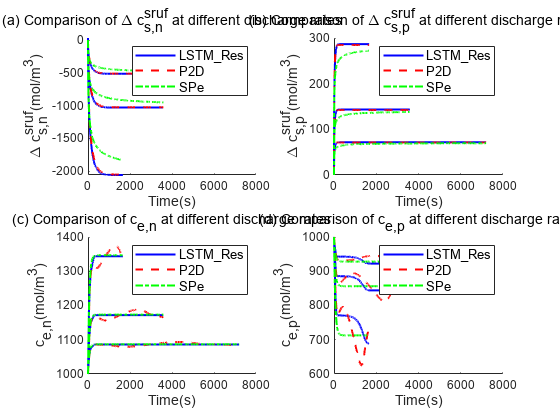

% exportgraphics(gcf,'test.png');
load trained_net\net_en_20230607.mat;
load trained_net\net_ep_20230607.mat;
load trained_net\net_sp_20230605.mat;
load trained_net\net_sn_20230605.mat;

net_dcsp=predict(net_sp,Jp');
net_dcsn=predict(net_sn,Jn');
net_cen=predict(net_en,[Jn';t])+1000;
net_cep=predict(net_ep,[Jn';t])+1000;

net_dcsp05=predict(net_sp,Jp05')*0.5;
net_dcsn05=predict(net_sn,Jn05')*0.5;
net_cen05=predict(net_en,[Jn05';t05])*0.5+1000;
net_cep05=predict(net_ep,[Jn05';t05])*0.5+1000;

net_dcsp2=predict(net_sp,Jp2')*2;
net_dcsn2=predict(net_sn,Jn2')*2;
net_cen2=predict(net_en,[Jn2';t2])*2+1000;
net_cep2=predict(net_ep,[Jn2';t2])*2+1000;

load comsol_data\load\dcsen_load.txt;
load comsol_data\load\dcsep_load.txt;
load comsol_data\cep_load.txt;
load comsol_data\cen_load.txt;
load comsol_data\load\dcsen_load05.txt;
load comsol_data\load\dcsep_load05.txt;
load comsol_data\load\cep_load05.txt;
load comsol_data\load\cen_load05.txt;
load comsol_data\load\dcsen_load2.txt;
load comsol_data\load\dcsep_load2.txt;
load comsol_data\load\cep_load2.txt;
load comsol_data\load\cen_load2.txt;

p2d_dcsn=dcsen_load(:,2);
p2d_dcsp=dcsep_load(:,2);
p2d_cen=cen_load(:,2);
p2d_cep=cep_load(:,2);
p2d_dcsn05=dcsen_load05(:,2);
p2d_dcsp05=dcsep_load05(:,2);
p2d_cen05=cen_load05(:,2);
p2d_cep05=cep_load05(:,2);
p2d_dcsn2=dcsen_load2(:,2);
p2d_dcsp2=dcsep_load2(:,2);
p2d_cen2=cen_load2(:,2);
p2d_cep2=cep_load2(:,2);

spe_dcsn=fom(Rsn,Dsn,Jn);
spe_dcsp=fom(Rsp,Dsp,Jp);
spe_dcsn05=fom(Rsn,Dsn,Jn05);
spe_dcsp05=fom(Rsp,Dsp,Jp05);
spe_dcsn2=fom(Rsn,Dsn,Jn2);
spe_dcsp2=fom(Rsp,Dsp,Jp2);
[spe_cen,spe_cep]=sp_electrolyte(I);
[spe_cen05,spe_cep05]=sp_electrolyte(I05);
[spe_cen2,spe_cep2]=sp_electrolyte(I2);

figure(2);
clf;
subplot(221);
hold on;
plot(net_dcsn,'b-',LineWidth=1.5);
plot(p2d_dcsn,'r--',LineWidth=1.5);
plot(spe_dcsn,'g-.',LineWidth=1.5);
plot(net_dcsn05,'b-',LineWidth=1.5);
plot(p2d_dcsn05,'r--',LineWidth=1.5);
plot(spe_dcsn05,'g-.',LineWidth=1.5);
plot(net_dcsn2,'b-',LineWidth=1.5);
plot(p2d_dcsn2,'r--',LineWidth=1.5);
plot(spe_dcsn2,'g-.',LineWidth=1.5);
title("(a) Comparison of \Delta c_{s,n}^{sruf} at different discharge rates",FontSize=11);
legend('LSTM\_Res','P2D','SPe',Fontsize=10);
xlabel('Time(s)',FontSize=11);
ylabel("\Delta c_{s,n}^{sruf}(mol/m^3)",FontSize=11);
subplot(222);
hold on;
plot(net_dcsp,'b-',LineWidth=1.5);
plot(p2d_dcsp,'r--',LineWidth=1.5);
plot(spe_dcsp,'g-.',LineWidth=1.5);
plot(net_dcsp05,'b-',LineWidth=1.5);
plot(p2d_dcsp05,'r--',LineWidth=1.5);
plot(spe_dcsp05,'g-.',LineWidth=1.5);
plot(net_dcsp2,'b-',LineWidth=1.5);
plot(p2d_dcsp2,'r--',LineWidth=1.5);
plot(spe_dcsp2,'g-.',LineWidth=1.5);
title("(b) Comparison of \Delta c_{s,p}^{sruf} at different discharge rates",FontSize=11);
legend('LSTM\_Res','P2D','SPe',FontSize=10);
xlabel('Time(s)',FontSize=11);
ylabel("\Delta c_{s,p}^{sruf}(mol/m^3)",FontSize=11);
subplot(223);
hold on;
plot(net_cen,'b-',LineWidth=1.5);
plot(p2d_cen,'r--',LineWidth=1.5);
plot(spe_cen,'g-.',LineWidth=1.5);
plot(net_cen05,'b-',LineWidth=1.5);
plot(p2d_cen05,'r--',LineWidth=1.5);
plot(spe_cen05,'g-.',LineWidth=1.5);
plot(net_cen2,'b-',LineWidth=1.5);
plot(p2d_cen2,'r--',LineWidth=1.5);
plot(spe_cen2,'g-.',LineWidth=1.5);
title("(c) Comparison of c_{e,n} at different discharge rates",FontSize=11);
legend('LSTM\_Res','P2D','SPe',FontSize=10);
xlabel('Time(s)',FontSize=11);
ylabel("c_{e,n}(mol/m^3)",FontSize=11);
subplot(224);
hold on;
plot(net_cep,'b-',LineWidth=1.5);
plot(p2d_cep,'r--',LineWidth=1.5);
plot(spe_cep,'g-.',LineWidth=1.5);
plot(net_cep05,'b-',LineWidth=1.5);
plot(p2d_cep05,'r--',LineWidth=1.5);
plot(spe_cep05,'g-.',LineWidth=1.5);
plot(net_cep2,'b-',LineWidth=1.5);
plot(p2d_cep2,'r--',LineWidth=1.5);
plot(spe_cep2,'g-.',LineWidth=1.5);
title("(d) Comparison of c_{e,p} at different discharge rates",FontSize=11);
legend('LSTM\_Res','P2D','SPe',FontSize=10);
xlabel('Time(s)',FontSize=11);
ylabel("c_{e,p}(mol/m^3)",FontSize=11);

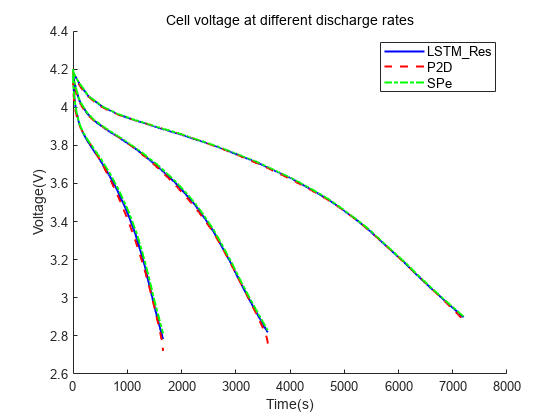

rmse(1,1)=RMSE(net_dcsn05',p2d_dcsn05);
rmse(1,2)=RMSE(spe_dcsn05,p2d_dcsn05);
rmse(1,3)=RMSE(net_dcsn',p2d_dcsn);
rmse(1,4)=RMSE(spe_dcsn,p2d_dcsn);
rmse(1,5)=RMSE(net_dcsn2',p2d_dcsn2);
rmse(1,6)=RMSE(spe_dcsn2,p2d_dcsn2);

rmse(2,1)=RMSE(net_dcsp05',p2d_dcsp05);
rmse(2,2)=RMSE(spe_dcsp05,p2d_dcsp05);
rmse(2,3)=RMSE(net_dcsp',p2d_dcsp);
rmse(2,4)=RMSE(spe_dcsp,p2d_dcsp);
rmse(2,5)=RMSE(net_dcsp2',p2d_dcsp2);
rmse(2,6)=RMSE(spe_dcsp2,p2d_dcsp2);

rmse(3,1)=RMSE(net_cen05',p2d_cen05);
rmse(3,2)=RMSE(spe_cen05',p2d_cen05);
rmse(3,3)=RMSE(net_cen',p2d_cen);
rmse(3,4)=RMSE(spe_cen',p2d_cen);
rmse(3,5)=RMSE(net_cen2',p2d_cen2);
rmse(3,6)=RMSE(spe_cen2',p2d_cen2);

rmse(4,1)=RMSE(net_cep05',p2d_cep05);
rmse(4,2)=RMSE(spe_cep05',p2d_cep05);
rmse(4,3)=RMSE(net_cep',p2d_cep);
rmse(4,4)=RMSE(spe_cep',p2d_cep);
rmse(4,5)=RMSE(net_cep2',p2d_cep2);
rmse(4,6)=RMSE(spe_cep2',p2d_cep2);

mape(1,1)=MAPE(net_dcsn05',p2d_dcsn05);
mape(1,2)=MAPE(spe_dcsn05,p2d_dcsn05);
mape(1,3)=MAPE(net_dcsn',p2d_dcsn);
mape(1,4)=MAPE(spe_dcsn,p2d_dcsn);
mape(1,5)=MAPE(net_dcsn2',p2d_dcsn2);
mape(1,6)=MAPE(spe_dcsn2,p2d_dcsn2);

mape(2,1)=MAPE(net_dcsp05',p2d_dcsp05);
mape(2,2)=MAPE(spe_dcsp05,p2d_dcsp05);
mape(2,3)=MAPE(net_dcsp',p2d_dcsp);
mape(2,4)=MAPE(spe_dcsp,p2d_dcsp);
mape(2,5)=MAPE(net_dcsp2',p2d_dcsp2);
mape(2,6)=MAPE(spe_dcsp2,p2d_dcsp2);

mape(3,1)=MAPE(net_cen05',p2d_cen05);
mape(3,2)=MAPE(spe_cen05',p2d_cen05);
mape(3,3)=MAPE(net_cen',p2d_cen);
mape(3,4)=MAPE(spe_cen',p2d_cen);
mape(3,5)=MAPE(net_cen2',p2d_cen2);
mape(3,6)=MAPE(spe_cen2',p2d_cen2);

mape(4,1)=MAPE(net_cep05',p2d_cep05);
mape(4,2)=MAPE(spe_cep05',p2d_cep05);
mape(4,3)=MAPE(net_cep',p2d_cep);
mape(4,4)=MAPE(spe_cep',p2d_cep);
mape(4,5)=MAPE(net_cep2',p2d_cep2);
mape(4,6)=MAPE(spe_cep2',p2d_cep2);

t_plus=0.363;
Rg=8.314;
T=298.15;
Rohm=1.2e-3;
soc_ave_p=soc0p+cumsum(-I)/3600/Qp;
soc_ave_n=soc0n+cumsum(I)/3600/Qn;
soc_surfp=soc_ave_p+net_dcsp'/csmaxpos;
soc_surfn=soc_ave_n+net_dcsn'/csmaxneg;
v_ce=(1+t_plus)*2*Rg*T/F*log(net_cep'./net_cen');
V_net=Eeqp(soc_surfp)-Eeqn(soc_surfn)+v_ce+I*Rohm;

soc_ave_p05=soc0p+cumsum(-I05)/3600/Qp;
soc_ave_n05=soc0n+cumsum(I05)/3600/Qn;
soc_surfp05=soc_ave_p05+net_dcsp05'/csmaxpos;
soc_surfn05=soc_ave_n05+net_dcsn05'/csmaxneg;
v_ce05=(1+t_plus)*2*Rg*T/F*log(net_cep05'./net_cen05');
V_net05=Eeqp(soc_surfp05)-Eeqn(soc_surfn05)+v_ce05+I05*Rohm;

soc_ave_p2=soc0p+cumsum(-I2)/3600/Qp;
soc_ave_n2=soc0n+cumsum(I2)/3600/Qn;
soc_surfp2=soc_ave_p2+net_dcsp2'/csmaxpos;
soc_surfn2=soc_ave_n2+net_dcsn2'/csmaxneg;
v_ce2=(1+t_plus)*2*Rg*T/F*log(net_cep2'./net_cen2');
V_net2=Eeqp(soc_surfp2)-Eeqn(soc_surfn2)+v_ce2+I2*Rohm;

load comsol_data\load\v_load.txt;
load comsol_data\load\v_load05.txt;
load comsol_data\load\v_load2.txt;
V_p2d=v_load(:,2);
V_p2d05=v_load05(:,2);
V_p2d2=v_load2(:,2);

sp_soc_surfp=soc_ave_p+spe_dcsp/csmaxpos;
sp_soc_surfn=soc_ave_n+spe_dcsn/csmaxneg;
sp_v_ce=(1+t_plus)*2*Rg*T/F*log(spe_cep'./spe_cen');
V_sp=Eeqp(sp_soc_surfp)-Eeqn(sp_soc_surfn)+I*Rohm+sp_v_ce;

sp_soc_surfp05=soc_ave_p05+spe_dcsp05/csmaxpos;
sp_soc_surfn05=soc_ave_n05+spe_dcsn05/csmaxneg;
sp_v_ce05=(1+t_plus)*2*Rg*T/F*log(spe_cep05'./spe_cen05');
V_sp05=Eeqp(sp_soc_surfp05)-Eeqn(sp_soc_surfn05)+sp_v_ce05+I05*Rohm;

sp_soc_surfp2=soc_ave_p2+spe_dcsp2/csmaxpos;
sp_soc_surfn2=soc_ave_n2+spe_dcsn2/csmaxneg;
sp_v_ce2=(1+t_plus)*2*Rg*T/F*log(spe_cep2'./spe_cen2');
V_sp2=Eeqp(sp_soc_surfp2)-Eeqn(sp_soc_surfn2)+sp_v_ce2+I2*Rohm;

figure(3);
clf;
hold on;
plot(V_net,'b-',LineWidth=1.5);
plot(V_p2d,'r--',LineWidth=1.5);
plot(V_sp,'g-.',LineWidth=1.5);
plot(V_net05,'b-',LineWidth=1.5);
plot(V_p2d05,'r--',LineWidth=1.5);
plot(V_sp05,'g-.',LineWidth=1.5);
plot(V_net2,'b-',LineWidth=1.5);
plot(V_p2d2,'r--',LineWidth=1.5);
plot(V_sp2,'g-.',LineWidth=1.5);
title("Cell voltage at different discharge rates",FontSize=11);
legend('LSTM\_Res','P2D','SPe',FontSize=10);
xlabel('Time(s)',FontSize=11);
ylabel("Voltage(V)",FontSize=11);


vrmse(1,1)=RMSE(V_net05,V_p2d05);
vrmse(2,1)=RMSE(V_sp05,V_p2d05);
vrmse(1,2)=RMSE(V_net,V_p2d);
vrmse(2,2)=RMSE(V_sp,V_p2d);
vrmse(1,3)=RMSE(V_net2,V_p2d2);
vrmse(2,3)=RMSE(V_sp2,V_p2d2);

vmape(1,1)=MAPE(V_net05,V_p2d05);
vmape(2,1)=MAPE(V_sp05,V_p2d05);
vmape(1,2)=MAPE(V_net,V_p2d);
vmape(2,2)=MAPE(V_sp,V_p2d);
vmape(1,3)=MAPE(V_net2,V_p2d2);
vmape(2,3)=MAPE(V_sp2,V_p2d2);

# 恒流充放

I_total=-17.5*[ones(2000,1);zeros(300,1);-ones(2000,1);zeros(3700,1)];
I8000=-17.5*[ones(8000,1)];
Jn8000=I8000*Rsn/3/epssn/F/A/Ln;
Jp8000=-I8000*Rsp/3/epssp/F/A/Lp;
t8000=1:length(I8000);

load comsol_data\cc\v_cc.txt;
load comsol_data\cc\socmean8000n.txt;
load comsol_data\cc\socmean8000p.txt;
V_p2d8000=v_cc(:,2);
socave8000n=socmean8000n(:,2);
socave8000p=socmean8000p(:,2);

tic
net_dcsp8000=predict(net_sp,Jp8000');
net_dcsn8000=predict(net_sn,Jn8000');
net_cen8000=predict(net_en,[Jn8000';t8000]);
net_cep8000=predict(net_ep,[Jn8000';t8000]);

net_cc_dcsn=LSTM_cc8000(net_dcsn8000);
net_cc_dcsp=LSTM_cc8000(net_dcsp8000);
net_cc_cen=LSTM_cc8000(net_cen8000)+1000;
net_cc_cep=LSTM_cc8000(net_cep8000)+1000;

soc_surfp8000=socave8000p+net_cc_dcsp'/csmaxpos;
soc_surfn8000=socave8000n+net_cc_dcsn'/csmaxneg;
v_ce8000=(1+t_plus)*2*Rg*T/F*log(net_cc_cep'./net_cc_cen');
V_net8000=Eeqp(soc_surfp8000)-Eeqn(soc_surfn8000)+v_ce8000+I_total*Rohm;
toc

历时 1.137765 秒。



tic
Jn_total=I_total*Rsn/3/epssn/F/A/Ln;
Jp_total=-I_total*Rsp/3/epssp/F/A/Lp;
soc_ave_p8000=soc0p+cumsum(-I_total)/3600/Qp;
soc_ave_n8000=soc0n+cumsum(I_total)/3600/Qn;
spe_dcsn8000=fom(Rsn,Dsn,Jn_total);
spe_dcsp8000=fom(Rsp,Dsp,Jp_total);
[spe_cen8000,spe_cep8000]=sp_electrolyte(I_total);

sp_soc_surfp8000=soc_ave_p8000+spe_dcsp8000/csmaxpos;
sp_soc_surfn8000=soc_ave_n8000+spe_dcsn8000/csmaxneg;
sp_v_ce8000=(1+t_plus)*2*Rg*T/F*log(spe_cep8000'./spe_cen8000');
V_sp8000=Eeqp(sp_soc_surfp8000)-Eeqn(sp_soc_surfn8000)+I_total*Rohm+sp_v_ce8000;
toc

历时 0.380799 秒。


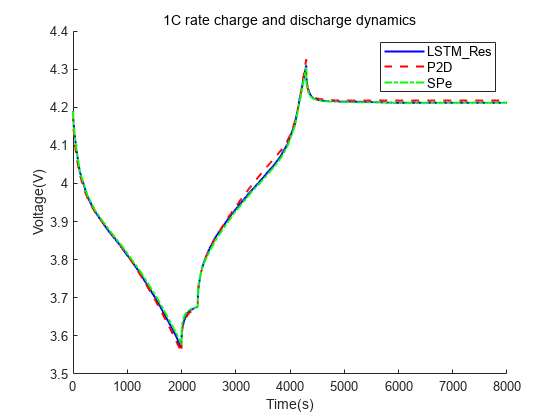

figure(4);
clf;
hold on;
plot(V_net8000,'b-','LineWidth',1.5);
plot(V_p2d8000,'r--',LineWidth=1.5);
plot(V_sp8000,'g-.',LineWidth=1.5);
title("1C rate charge and discharge dynamics",FontSize=11);
legend('LSTM\_Res','P2D','SPe',FontSize=10);
xlabel('Time(s)',FontSize=11);
ylabel("Voltage(V)",FontSize=11);

v_error(1,1)=RMSE(V_net8000,V_p2d8000)*1000;
v_error(1,2)=RMSE(V_sp8000,V_p2d8000)*1000;
v_error(2,1)=MAPE(V_net8000,V_p2d8000);
v_error(2,2)=MAPE(V_sp8000,V_p2d8000);